# Fluorescence excitation spectra

% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  
init;

**Species**

species = availableSpecies(4);


*     Add new species in .mat format under ".\LIFSim4.0\input-data\lines\" , *

*    see documentation section "Importing lines and partition function" for details*

**Laser parameters**

unit = '1/cm';
defStep = 0.05;
if strcmpi(unit,'nm') 
    defStep = 0.0001;
end
%224.97 - 225.22 ~ 44400 - 44450
startwn = 43278 ;
checkWnum(unit,startwn);
endwn = 43300;
checkWnum(unit,endwn);
step = 0.015001;
dnuGL = 0.2;
dnuLL = 0.01;

**Environment **

T = 1400;
P = 1;


   * Pressure is only considered if collision model available (NO)*

dnuL = 0.01;
dnuSh = 0; 
colls =  collisions(species);


excWnum = startwn:step:endwn;
plotWnum = excWnum;
if strcmpi(unit,'nm') 
    excWnum = convWnumWlen(excWnum);
    dnuGL = convWnumWlen(dnuGL,endwn);
    dnuLL = convWnumWlen(dnuLL, endwn);
    dnuL = convWnumWlen(dnuL, endwn);
end

[linelist, Z, n, ~,MM, emList] = selectLines(species,excWnum );

if n == 0    
    warning("No lines found.")
    return;
end


**Collisions data**

if ~isempty(colls)
path = "input-data\gas-compositions\air+NO.csv";

     *(For Support for NO, otherwise update function 'collissions')*


gas = loadGasComposition(path);

[dnuL, dnuSh] = collisionalBroadening(gas, colls, P, T);
[quen,linelist] = quenchRate(gas, colls, T,P, MM, linelist);
 
end


**Detection filter**

Keep empty to ignore filter

pathFilter = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\filters\sio.Notch.0deg.xlsx";
fileUnit = 'nm';
if isfile(pathFilter)
    filter = loadSpectrum(pathFilter,fileUnit);
    linelist = fluorTransm(linelist, emList, filter);
end


spec = excitationSpec(excWnum,...
    linelist,...
    MM, ...
    T,...
    dnuGL,... % laser linewidth, Gauss
    dnuLL,... % laser linewidth, Lorentz
    dnuL=dnuL,... % line linelinewidth, Lorentz
    Z= Z, dnuSh=dnuSh...
    );

if strcmpi(unit,'nm') 
    spec = fliplr(spec);
end


## **Result plot**    

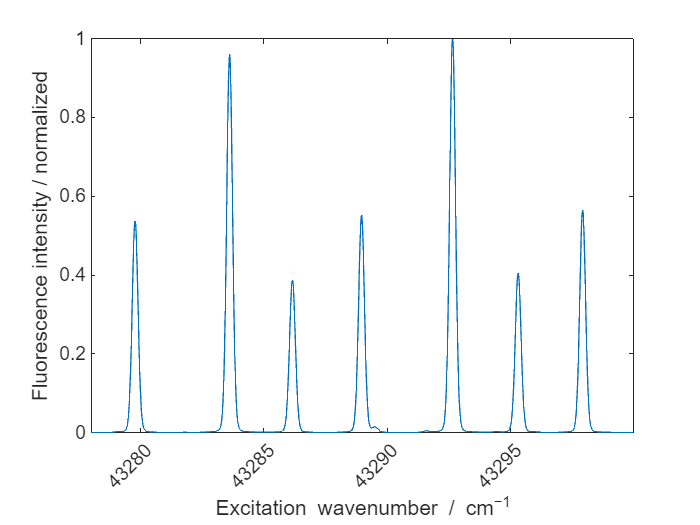

 

f = figure;

plot(plotWnum, spec)
xlim([plotWnum(1) plotWnum(end)])


LABELS(unit);

LABELS('flourIntNorm');